musicname="data\599-60.wav";
jpegname="data\599-60.jpg";
musicJname="data\599-60-J.wav";

[matrix2D,fs]=music2jpeg(musicname,jpegname);
music_J=jpeg2music(jpegname,musicJname,fs);

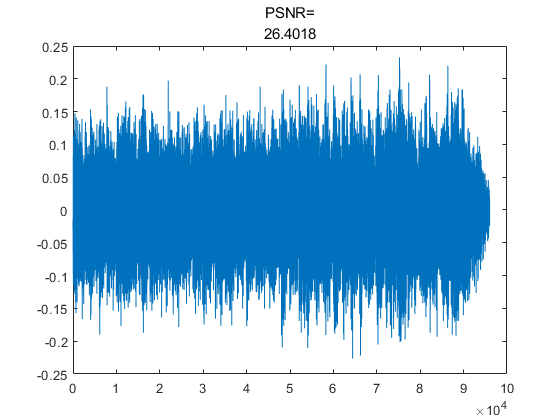

[music,~]=audioread(musicname);
music=music';
music=music/(max(music)-min(music))*2; % normalization
music_J(length(music)+1:end)=[]; % cut mute part

plot([0:length(music)-1],music_J-music);
MSE=sum((music-music_J).^2,"all")/numel(music);
PSNR=10*log10(1^2/MSE);
title("PSNR=",num2str(PSNR));